# Using MATLAB to graph derivatives

## Functions

You can define a function using the anonymous function synt

fun = @(x) sin(1./(x.*(2-x))).^2;

Then define a certain domain of x values you would like to work with. I'm picking values around zero because that's where `fun` misbehaves

x=linspace(-0.3,0.3,250)';

Let's just see how the forward difference, central difference and some higher order term compare

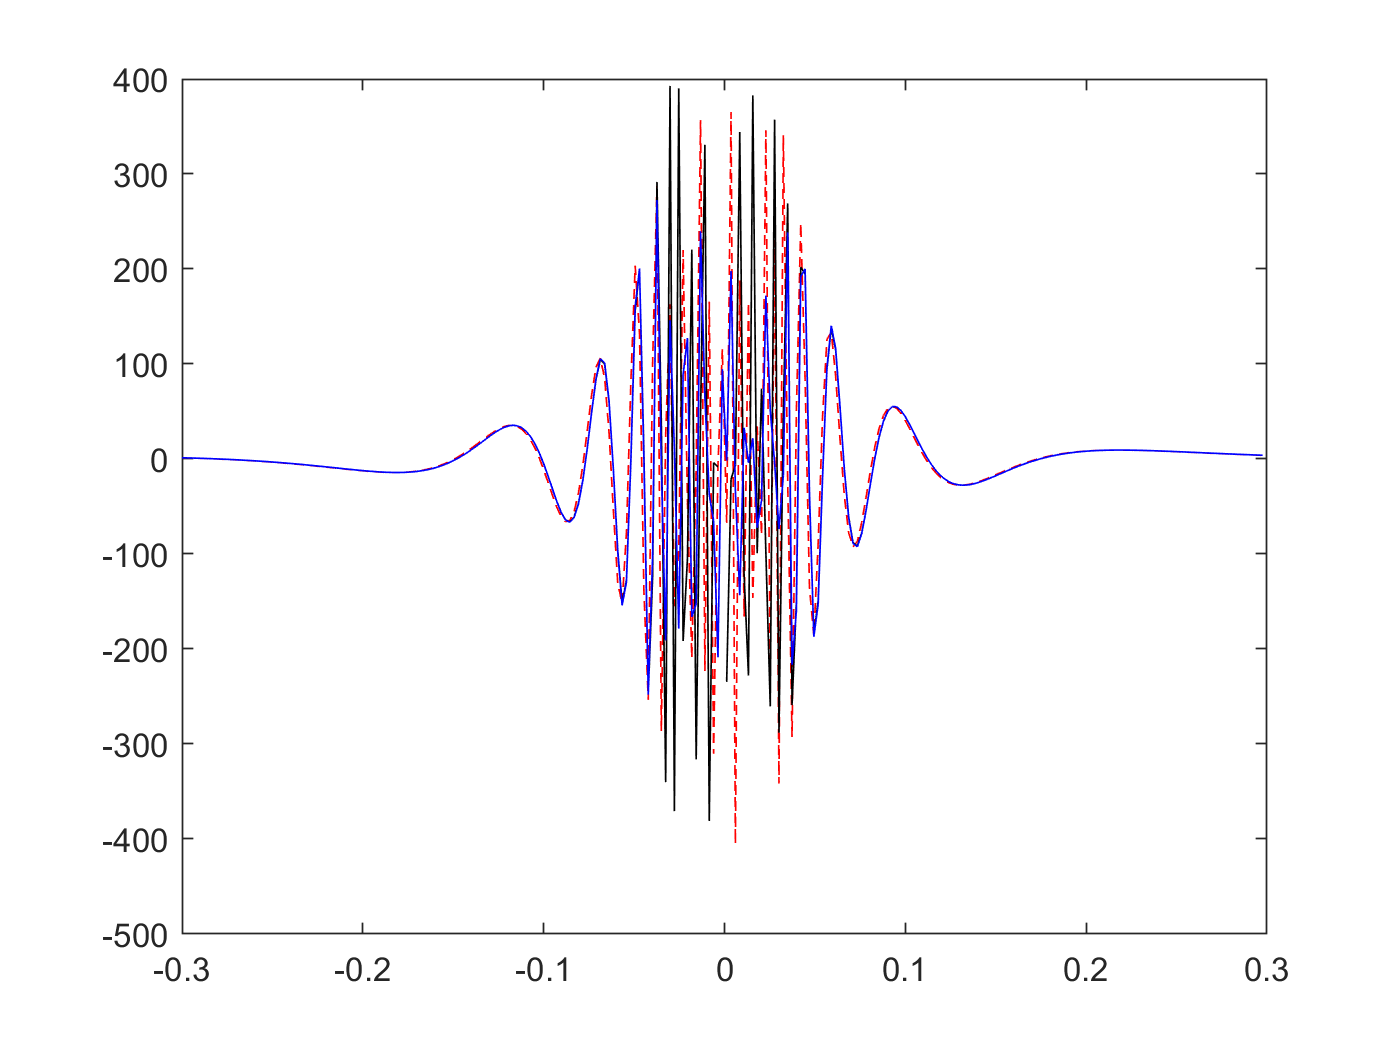

[dyf,dxf]= Der(fun,x,'fd');
[dyc,dxc]= Der(fun,x,'cd');
[dyh,dxh]= Der(fun,x,'hod');
plot(dxf,dyf,'r--',dxc,dyc,'k-',dxh,dyh,'b-')

See the the percentage difference between the higher order and the forward difference

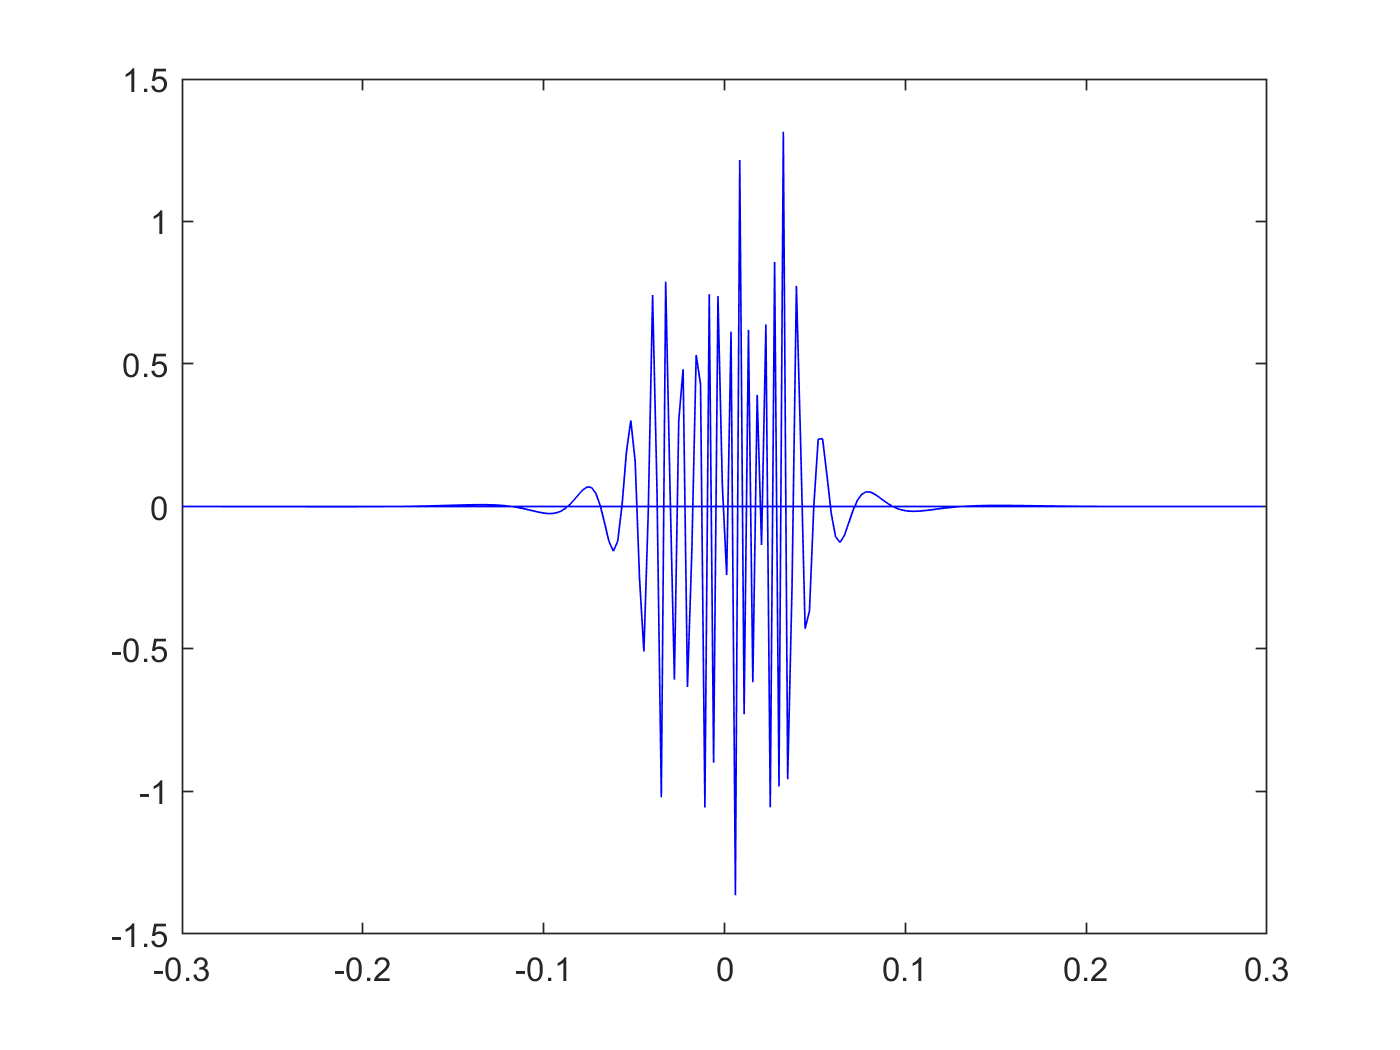

plot(dxf,(dyf-dyh)/dyh,'b-')

The disagreement among methods is obviously the greatest when the function varies the fastest.

## Data

When storing data in .mat files, you can use the `load` function to access the variables (in this case `X` and` Y`).

load('derdata.mat')

Again lets see how different methods handle this data

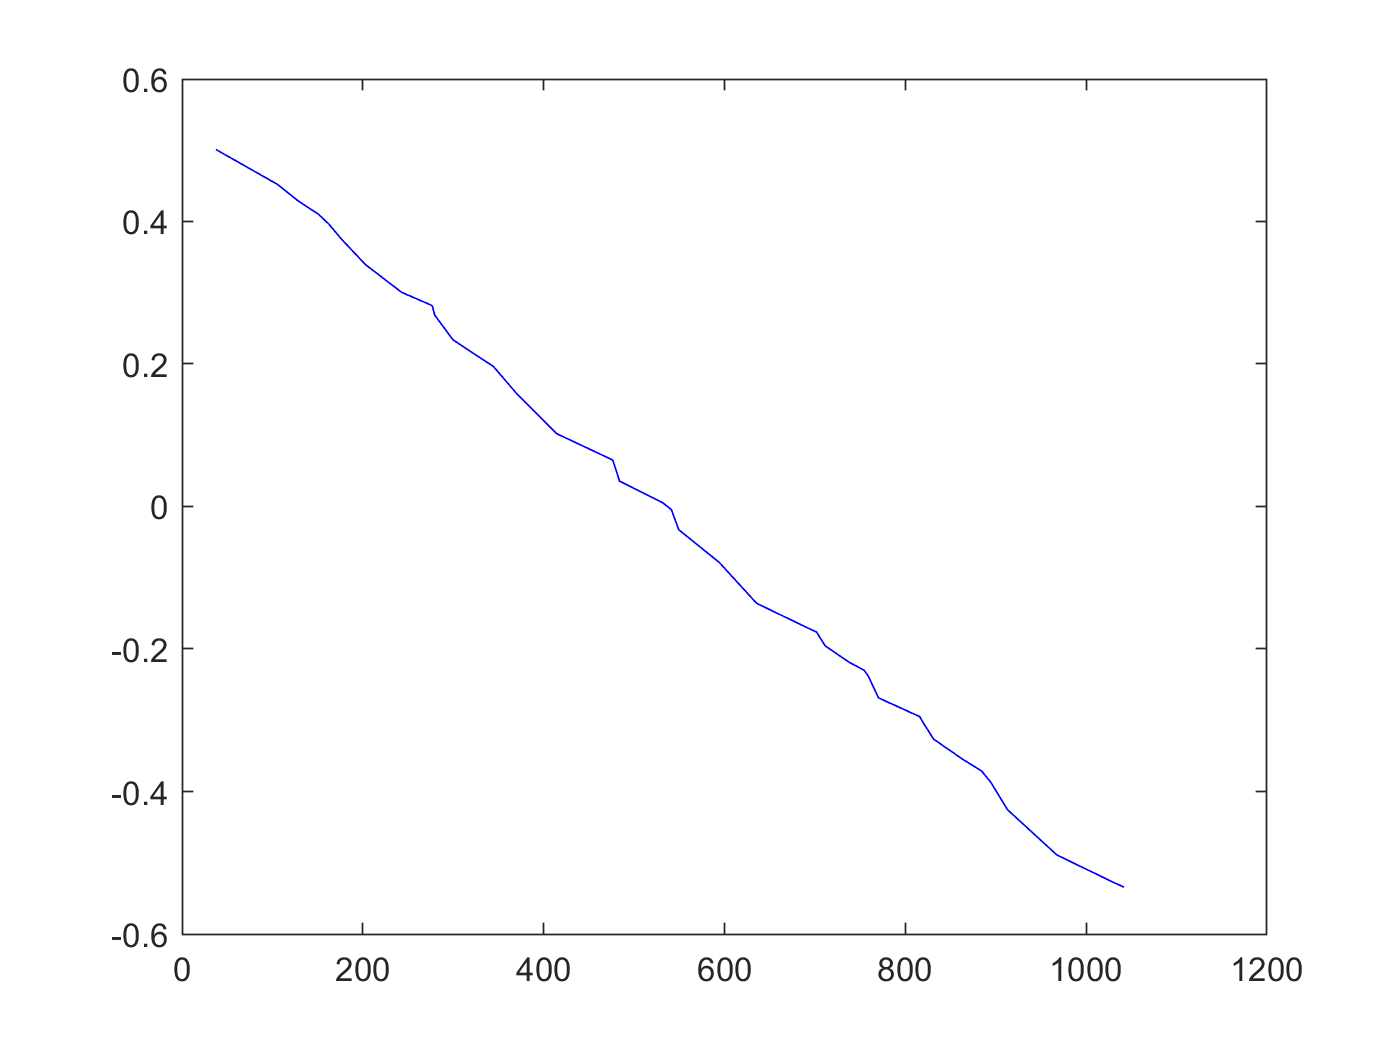

[dyf,dxf]= Der(Y,X,'fd');
[dyc,dxc]= Der(Y,X,'cd');
[dyh,dxh]= Der(Y,X,'hod');
figure
plot(dxf,dyf,'r--',dxc,dyc,'k-',dxh,dyh,'b-')

You cannot tell the lines apart because they are the same.

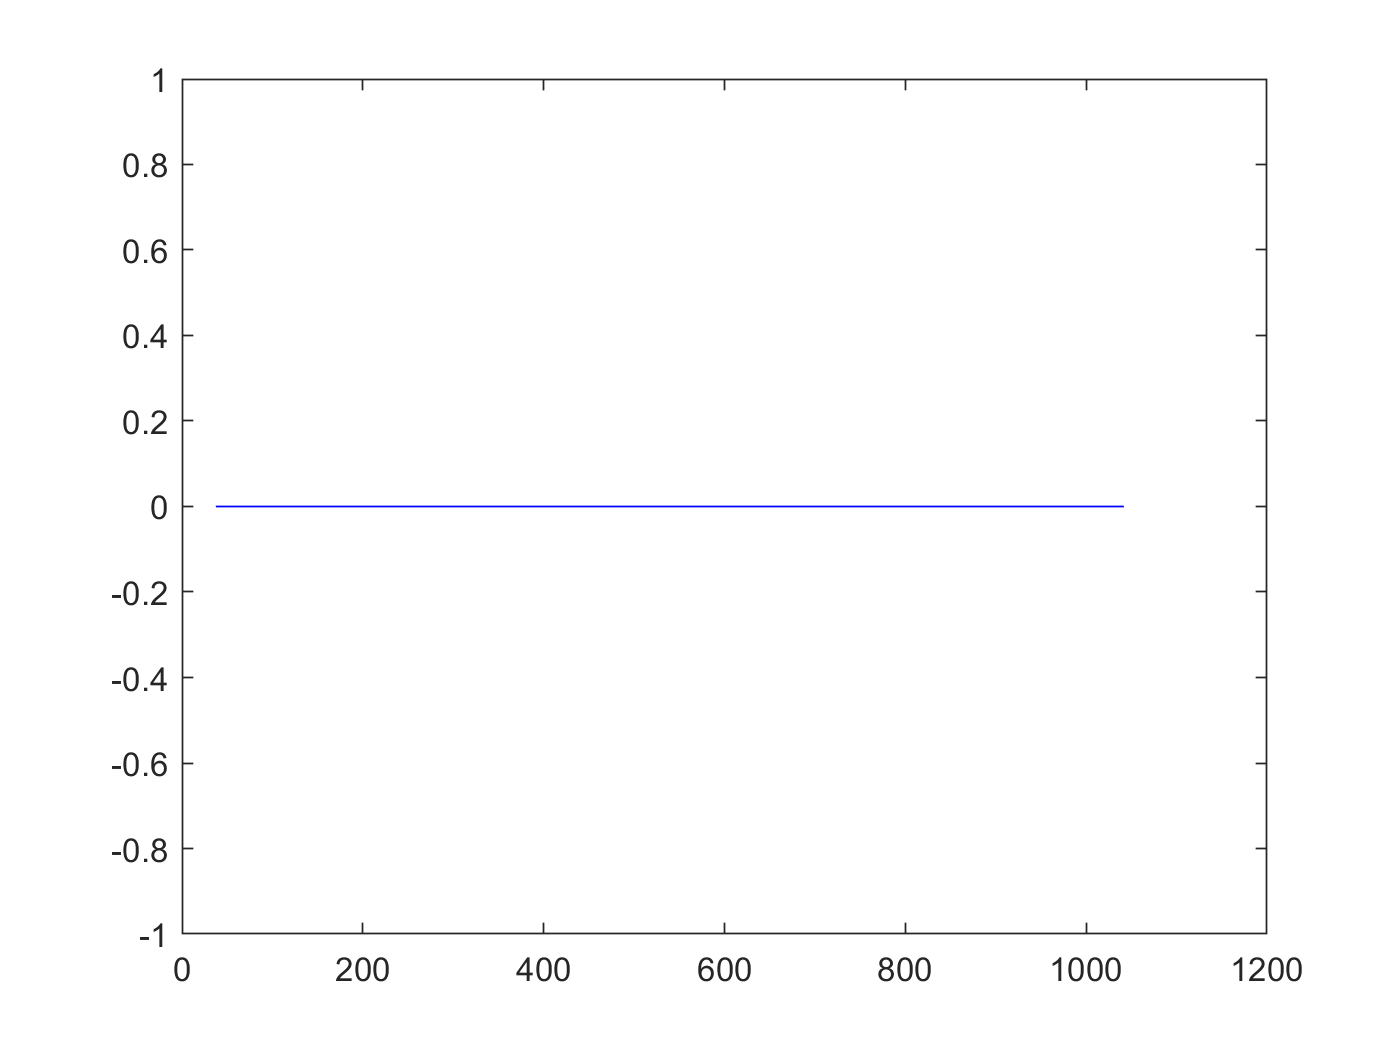

plot(dxf,dyf-dyh,'b-')

In fact with data (that is widely spaced), you gain no advantage with higher-order methods. You might as well use the built-in function `diff, `it gives the same answer.

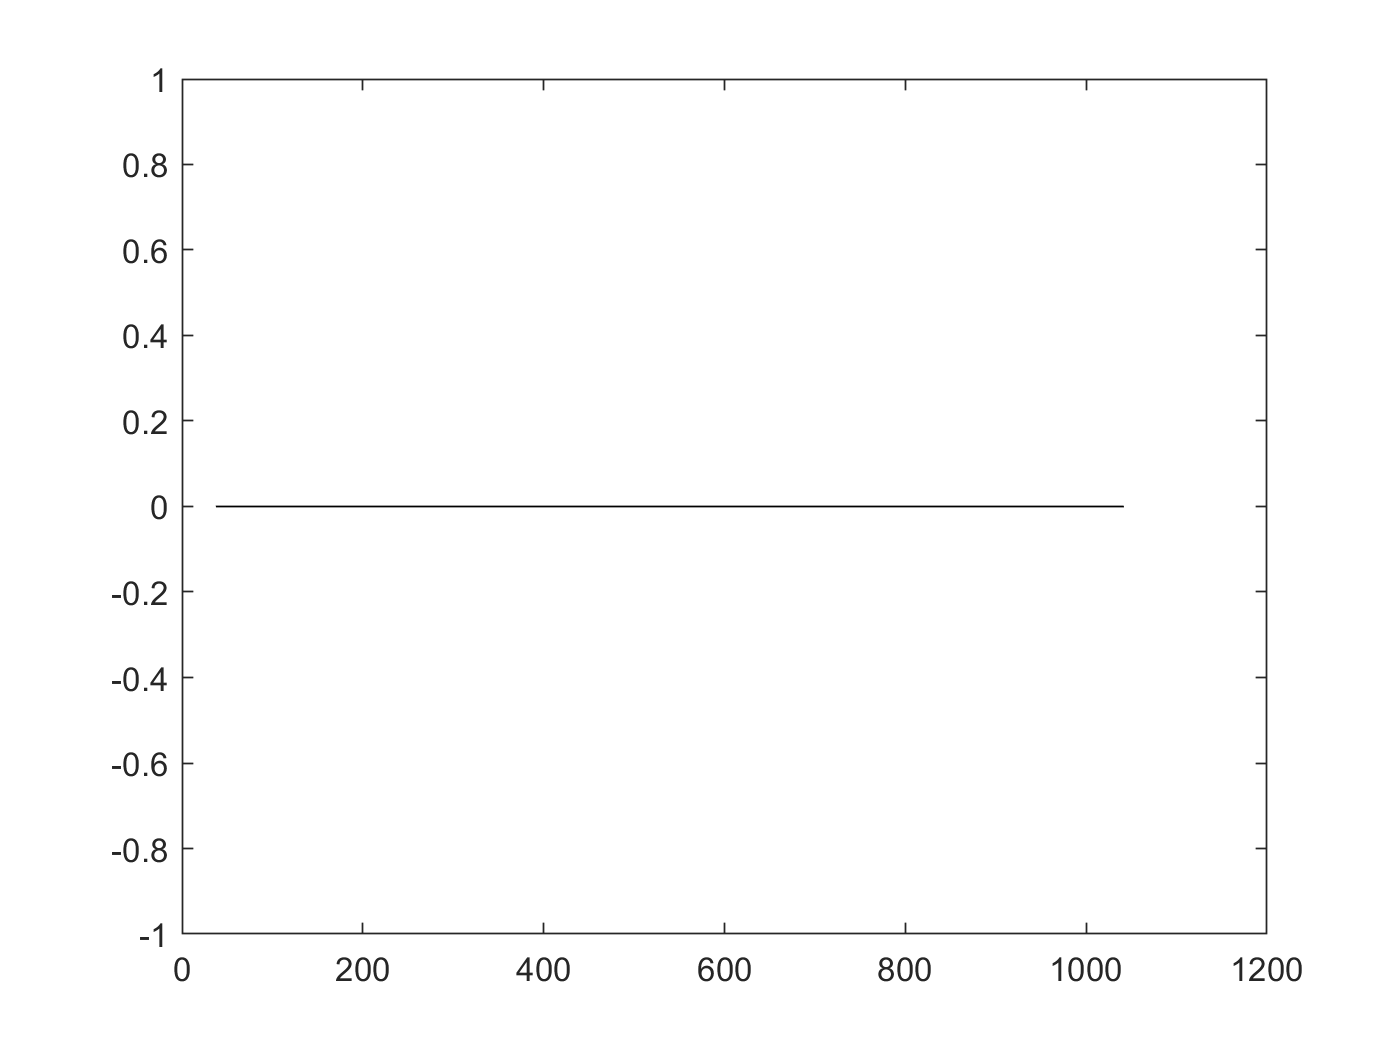

plot(dxh,dyh-diff(Y)./diff(X),'k-')

The second derivative can be found using *diff* as well

ydprime = diff(Y,2)./diff(X,2)

ydprime =    0.527374003820055
   0.662819781850140
   0.449039569598072
   0.340720582800605
   0.348443633399023
   0.271656162010779
   0.523382838290288
   0.300938679896791
   0.279505295755031
   0.266515524641086


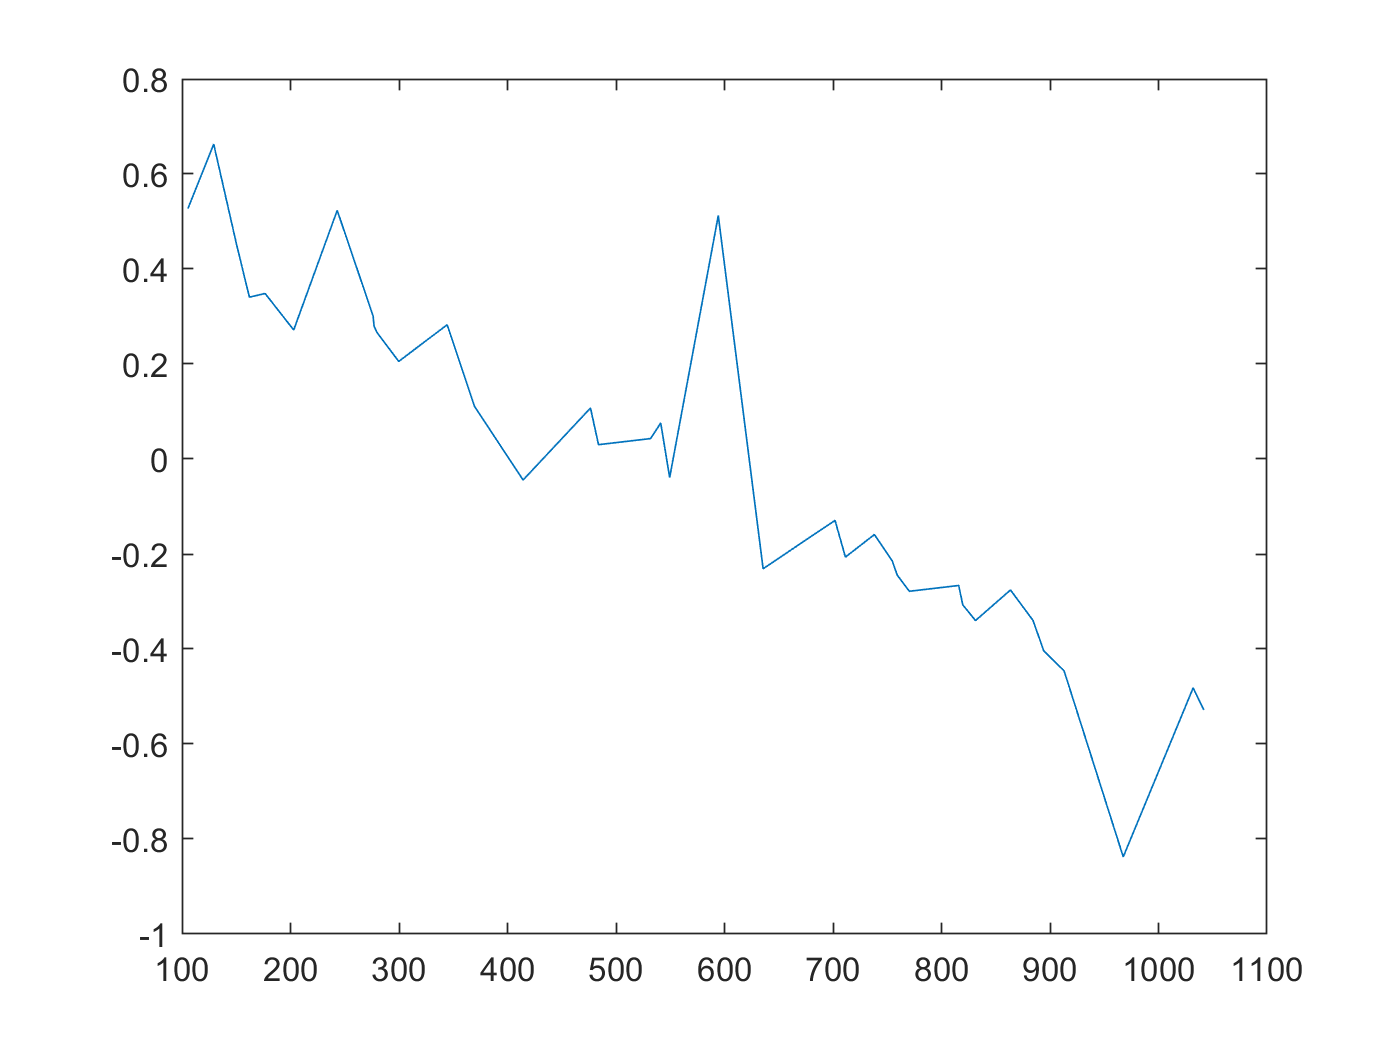

plot(X(2:end-1),ydprime)